# Read all the images 

clear;clc; close all;
%Change enable to 1 if you want to check the progression of image
%segmentation
enable=0;
if(enable==0)
    fprintf("Intermediate images will not be printed\n");
else
    fprintf("Intermediate images will be printed\n");
end

Intermediate images will not be printed



% height and width of the image to analyse
h=256;w=256;

% Directory path 
directory = 'Datasets\Task1\Images'; % Folder where the images are stores
folderpath='Train'; % Folder where we want so save the images with masks to

% Get a list of all files in the directory
fileList = dir(fullfile(directory, '*.jpg'));

% Loop through the list and read each image
%If you want to test all the images just change the 5 for numel(fileList)
images = cell(1, numel(fileList)); % Initialize cell array to store images
Bounding = cell(1, numel(fileList));
list=[1 ,2 ,9 ,29 ,38 ];

for i = 1:numel(fileList)

    % Get the file name
    fileName = fullfile(directory, fileList(i).name);
    
    % Read and resize the image
    image = imresize(imread(fileName),[h w]);
    
    % Store the image in the cell array
    
    images{i} = image;

end

% Display the images like and the respectives histograms
if(enable==1)
    figure;
    figure;
    subplot(2,5,1);imshow(images{1});title('Image 1');
    subplot(2,5,2);imshow(images{2});title('Image 2');
    subplot(2,5,3);imshow(images{3});title('Image 3');
    subplot(2,5,4);imshow(images{4});title('Image 4');
    subplot(2,5,5);imshow(images{5});title('Image 5');
    subplot(2,5,6);imhist(images{1});title('Histogram 1');
    subplot(2,5,7);imhist(images{2});title('Histogram 2');
    subplot(2,5,8);imhist(images{3});title('Histogram 3');
    subplot(2,5,9);imhist(images{4});title('Histogram 4');
    subplot(2,5,10);imhist(images{5});title('Histogram 5');
end


## Pre-processing

Row: 256
Row: 219
First Row: 219 Last Row: 256
Rist Row: 219


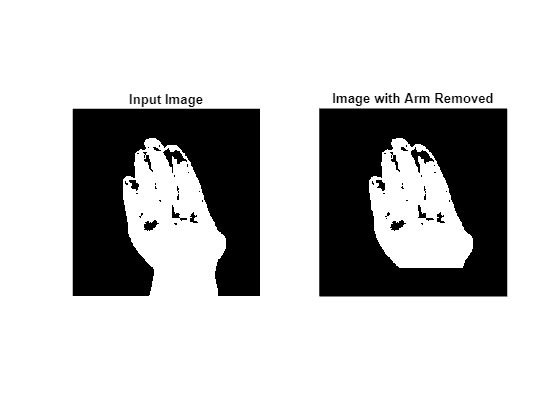

Row: 256
Row: 252
First Row: 252 Last Row: 256
Rist Row: 252


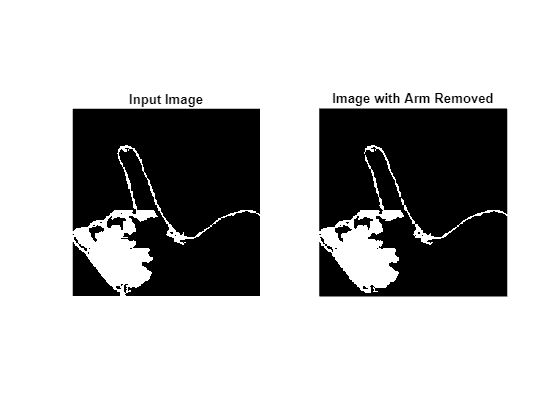

Row: 256
Row: 250
First Row: 250 Last Row: 104
Rist Row: 104


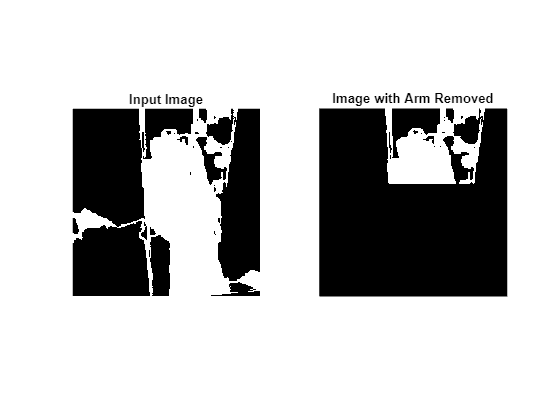

Row: 256
Row: 251
First Row: 251 Last Row: 256
Rist Row: 251


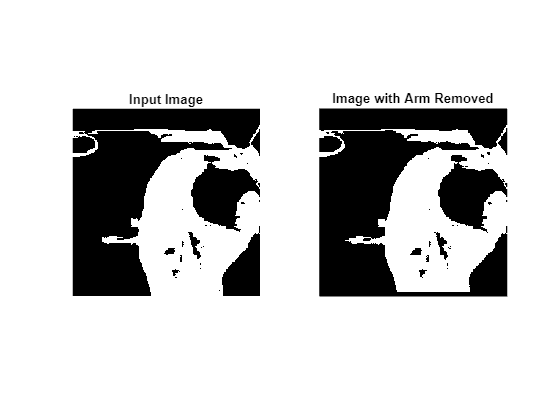

Row: 256
Row: 252
First Row: 252 Last Row: 256
Rist Row: 252


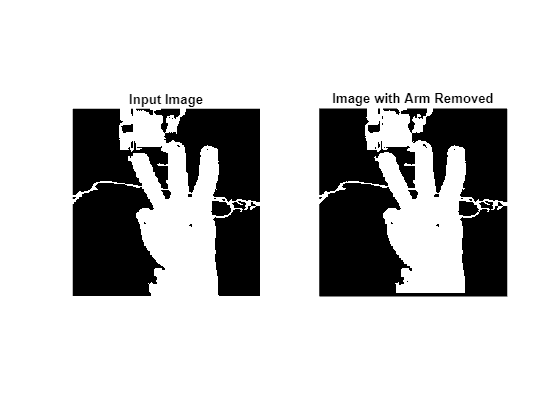

Row: 255
Row: 251
First Row: 251 Last Row: 122
Rist Row: 122


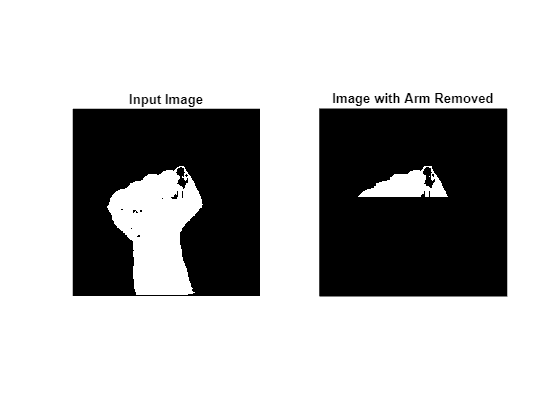

Row: 256
Row: 225
First Row: 225 Last Row: 256
Rist Row: 225


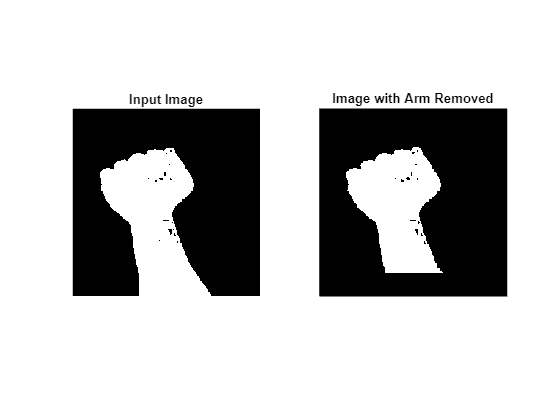

Row: 256
Row: 254
First Row: 254 Last Row: 226
Rist Row: 226


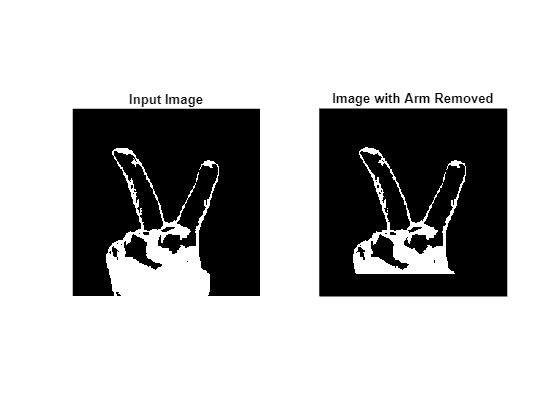

Row: 256
Row: 209
First Row: 209 Last Row: 256
Rist Row: 209


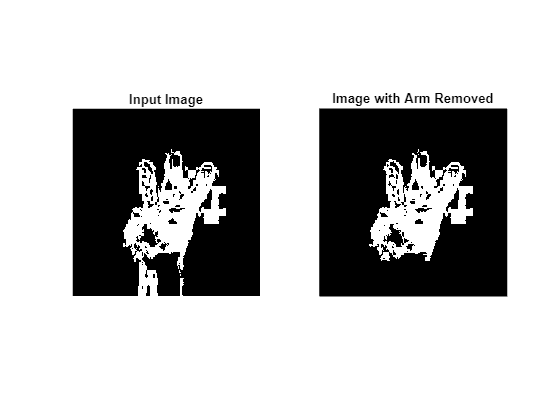

Row: 256
Row: 255
First Row: 255 Last Row: 256
Rist Row: 255


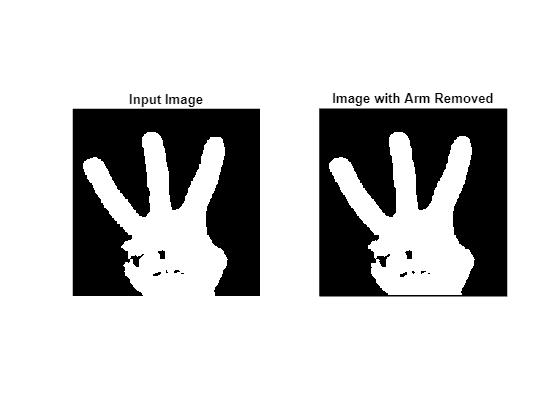

Row: 256
Row: 205
First Row: 205 Last Row: 256
Rist Row: 205


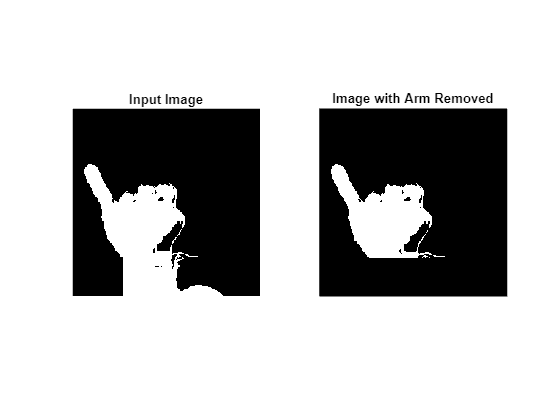

Row: 153
Row: 132
First Row: 132 Last Row: 153
Rist Row: 132


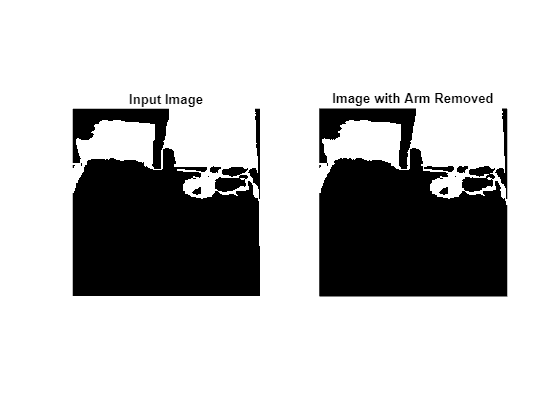

Row: 256
Row: 247
First Row: 247 Last Row: 256
Rist Row: 247


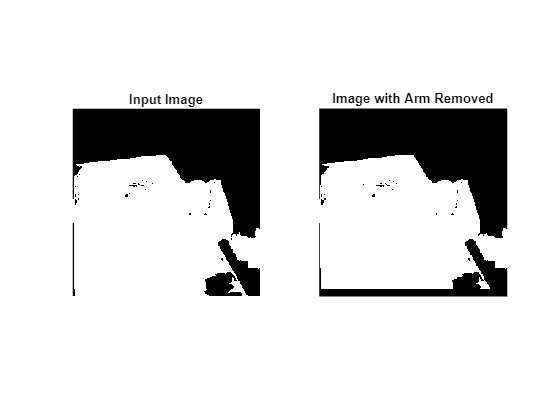

Row: 256
Row: 237
First Row: 237 Last Row: 256
Rist Row: 237


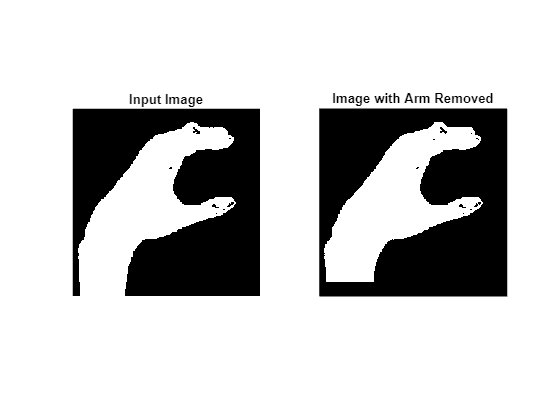

Row: 256
Row: 250
First Row: 250 Last Row: 256
Rist Row: 250


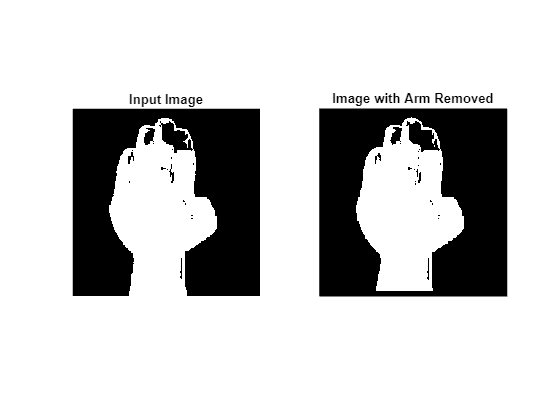

Row: 256
Row: 233
First Row: 233 Last Row: 256
Rist Row: 233


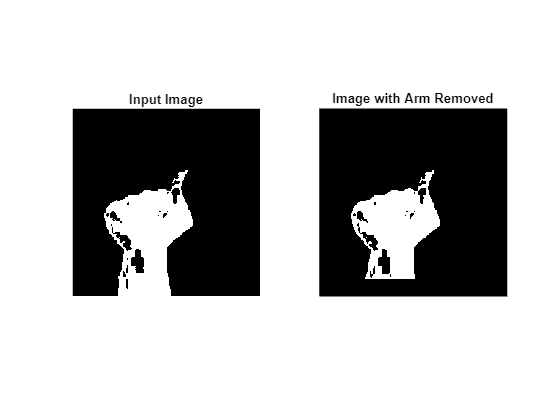

Row: 256
Row: 245
First Row: 245 Last Row: 256
Rist Row: 245


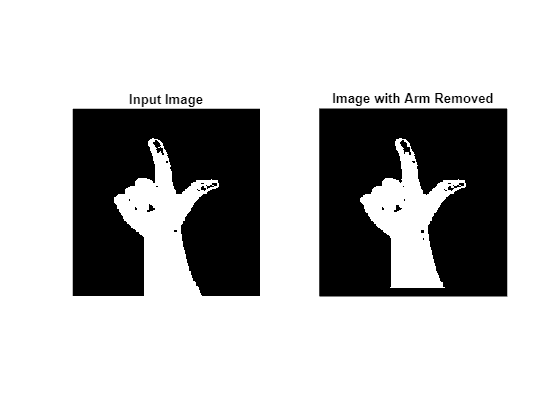

Row: 256
Row: 230
First Row: 230 Last Row: 254
Rist Row: 230


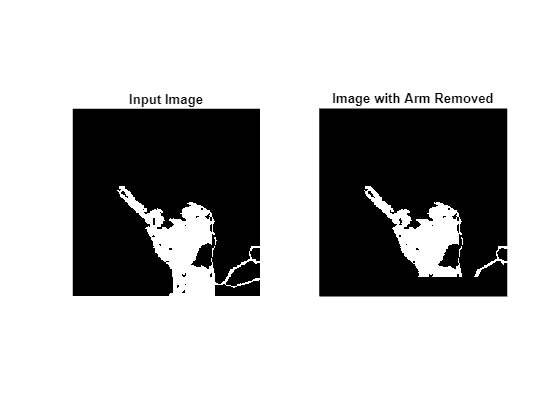

Row: 256
Row: 206
First Row: 206 Last Row: 256
Rist Row: 206


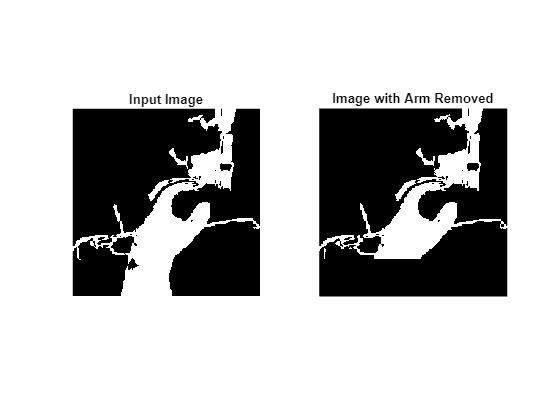

Row: 256
Row: 244
First Row: 244 Last Row: 254
Rist Row: 244


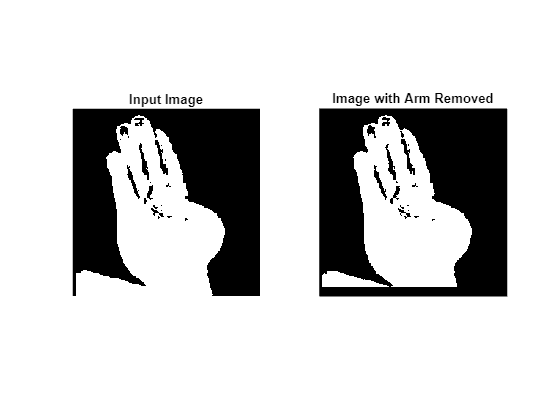

Row: 256
Row: 255
First Row: 255 Last Row: 252
Rist Row: 252


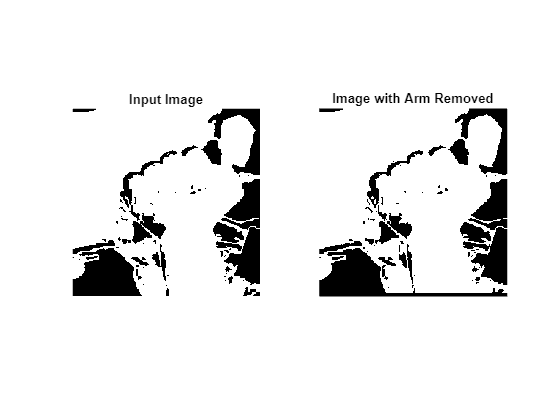

Row: 256
First Row: 256 Last Row: 247
Rist Row: 247


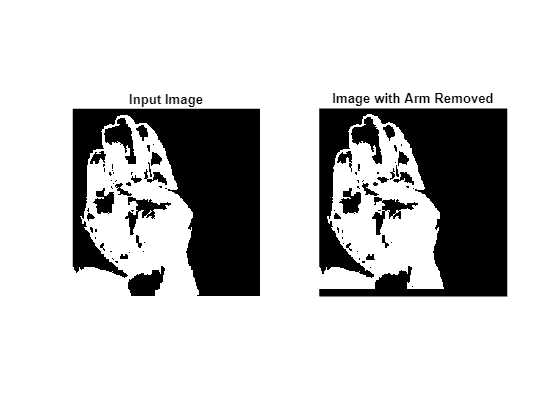

Row: 256
Row: 252
First Row: 252 Last Row: 256
Rist Row: 252


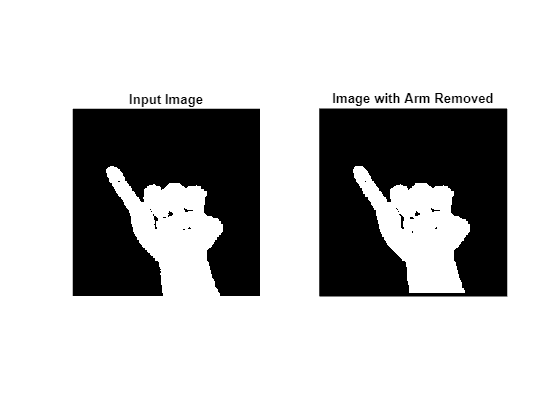

Row: 256
Row: 251
First Row: 251 Last Row: 256
Rist Row: 251


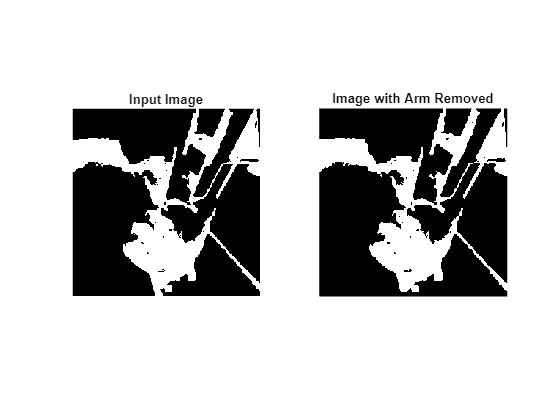

Row: 256
Row: 255
First Row: 255 Last Row: 256
Rist Row: 255


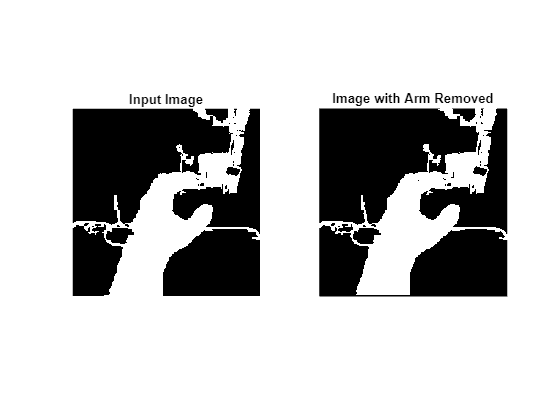

Row: 256
Row: 253
First Row: 253 Last Row: 256
Rist Row: 253


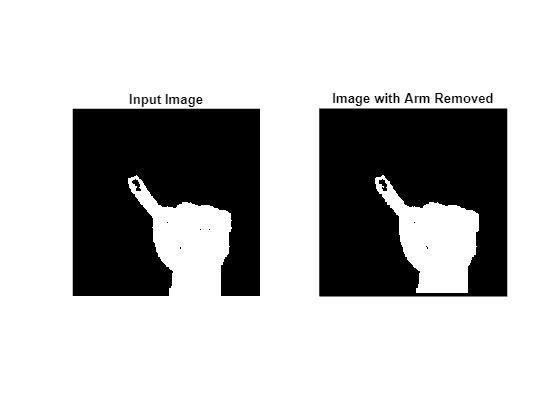

Row: 256
Row: 251
First Row: 251 Last Row: 256
Rist Row: 251


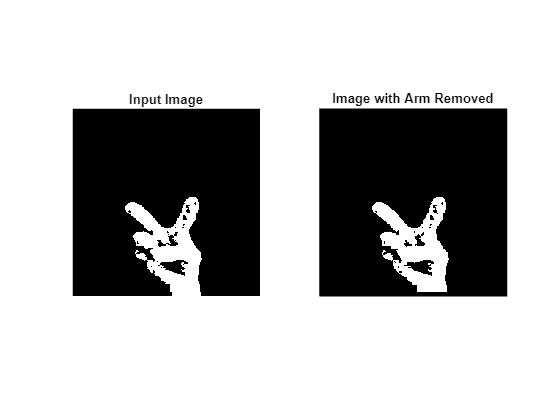

Row: 255
Row: 254
First Row: 254 Last Row: 240
Rist Row: 240


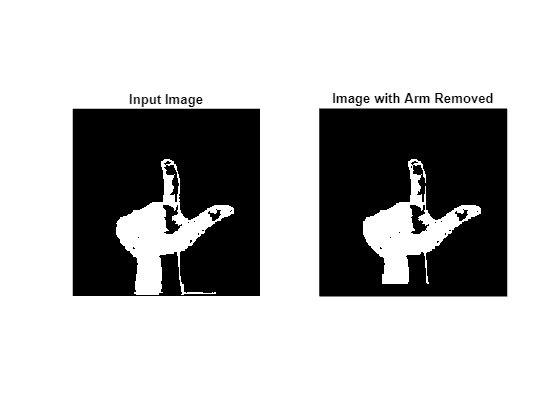

Row: 239
Row: 234
First Row: 234 Last Row: 223
Rist Row: 223


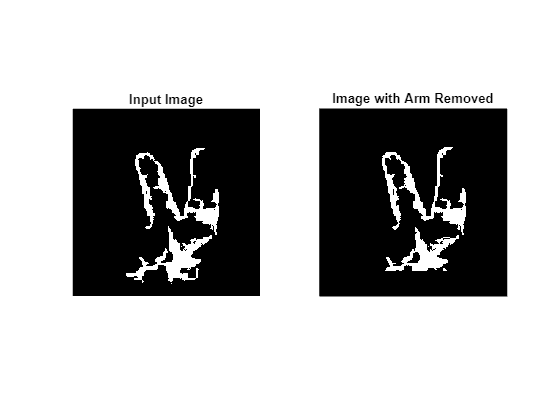

Row: 256
Row: 254
First Row: 254 Last Row: 224
Rist Row: 224


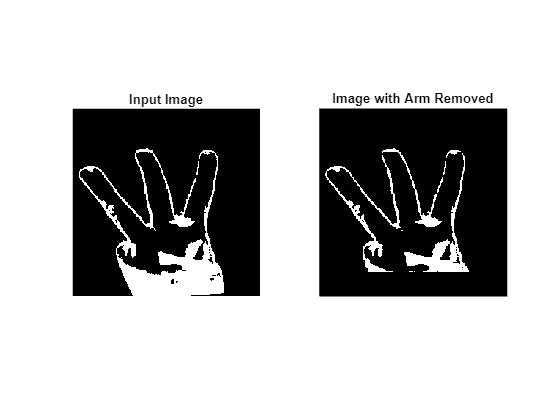

Row: 256
Row: 226
First Row: 226 Last Row: 256
Rist Row: 226


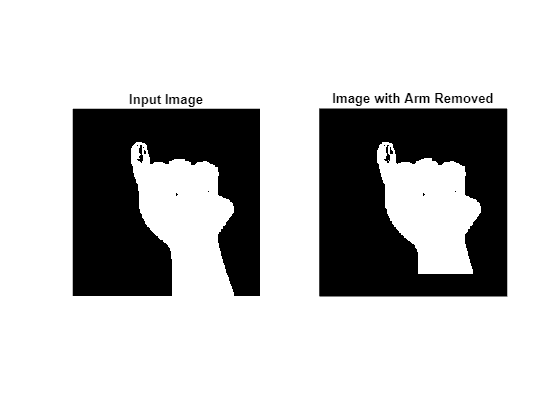

Row: 256
Row: 255
First Row: 255 Last Row: 256
Rist Row: 255


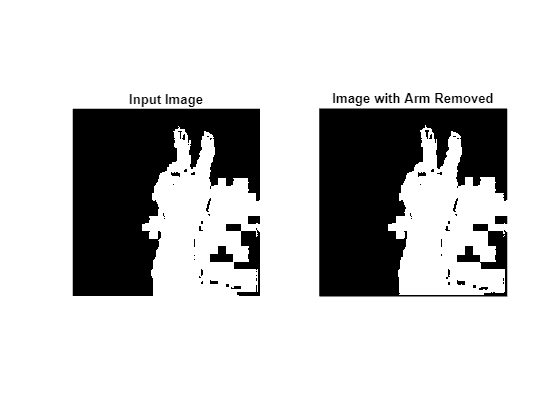

Row: 256
Row: 248
First Row: 248 Last Row: 256
Rist Row: 248


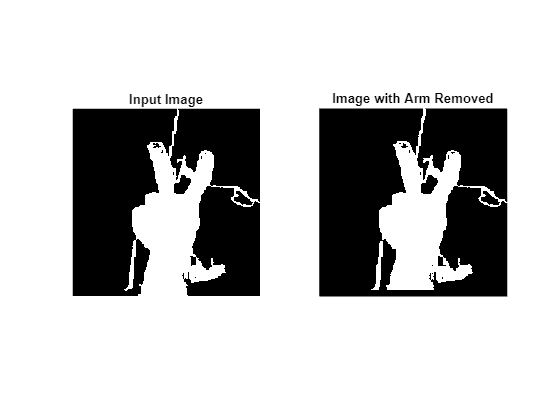

Row: 256
Row: 217
First Row: 217 Last Row: 256
Rist Row: 217


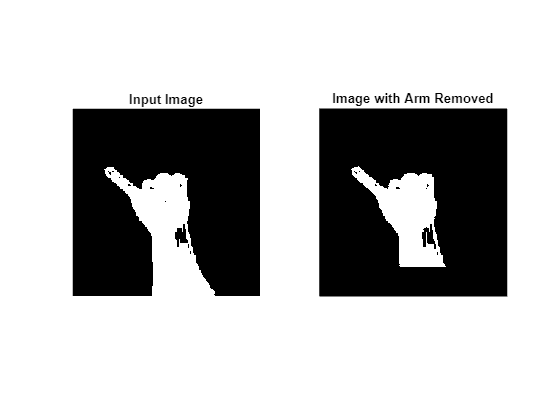

Row: 256
Row: 251
First Row: 251 Last Row: 256
Rist Row: 251


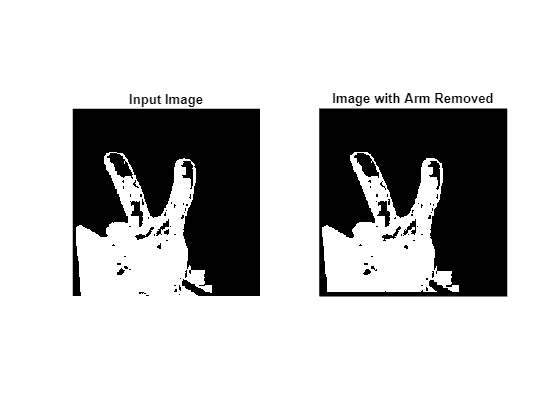

Row: 256
Row: 253
First Row: 253 Last Row: 9
Rist Row: 9


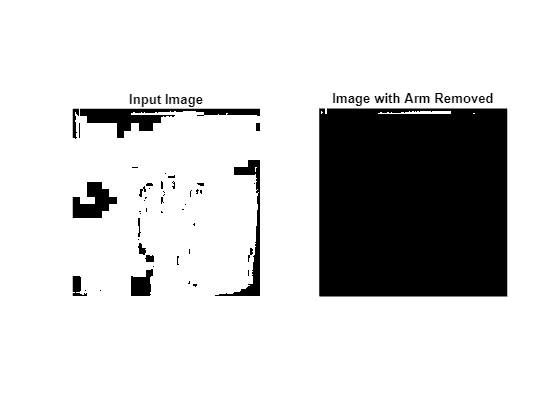

Row: 256
Row: 255
First Row: 255 Last Row: 256
Rist Row: 255


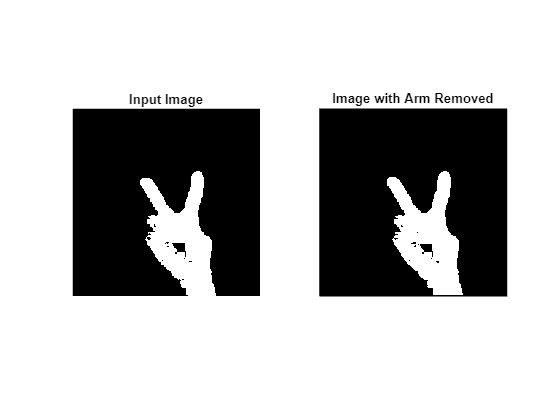

Row: 256
Row: 171
First Row: 171 Last Row: 256
Rist Row: 171


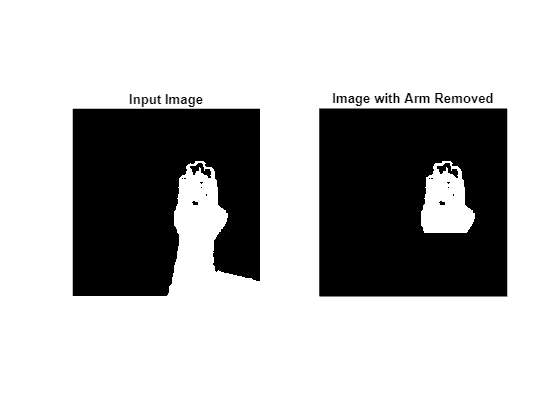

%Using just one image to test
%se1=strel('sphere',10);

for j=1:numel(fileList)
    Img=images{j};
        
    %YCbCr
    YCbCr=rgb2ycbcr(Img);
    Cb=YCbCr(:,:,2);
    Cr=YCbCr(:,:,3); 
    %HSV
    HSV=rgb2hsv(Img);

    [r,c,~]=find(Cr >= 140 & Cr <= 160 & Cb >= 95 & Cb <= 170 & HSV(:,:,1)<0.9);
    
    % fprintfEnd1');

    Img_S_e = zeros(h, w);
    numind = size(r);

    for i=1:numind
        Img_S_e(r(i),c(i)) = 1;
    end

    %Img_open=imopen(Img_S_e,se1);

    % figure();
    % subplot(1,2,1);imshow(Img_S_e);
    % subplot(1,2,2);imshow(Img_open);
    % if(j<=2)
    %     if(j==1)
    %         figure();
    %         subplot(1,2,1);imshow(Img_S_e);
    %     else
    %         subplot(1,2,2);imshow(Img_S_e);
    %     end
    % else
    %     if(j==3)
    %         figure;
    %     end
    %     subplot(6,6,j-2);imshow(Img_S_e);
    % 
    % end

    [L,n]=bwlabel(Img_S_e);

    s=regionprops(L,'PixelIdxList','Area','BoundingBox','Centroid');
    a_max=0;
    i_max=0;

    idx=[s.Area]>=5000;
    if(find(idx==1))
        idx_to_keep = [s.Area] >= 5000;
        s=s(idx_to_keep);
    else
        idx_to_keep = [s.Area] >= 2000;
        s=s(idx_to_keep);
    end

    
    m=1;
    skin_px = zeros(h, w);
    for i = 1:size(idx_to_keep,2)
        if(idx_to_keep(i)==1)
            [r,c,~] = find(L==i);
            numind = size(r,1);
            for k=1:numind
                skin_px(r(k),c(k)) = 1;
            end
            % if(m==1)
            %     figure;
            % end
            % filename=sprintf("Id %d",m);
            % if(size(s,1)==1)
            %     imshow(skin_px);title(filename);
            % elseif(size(s,1)>1)
            % 
            %     subplot(1,size(s,1),m);imshow(skin_px);title(filename);
            %     m=m+1;
            % end
        end
    end

    


    %this will remove the arm from the picture and print it if enable=1
    % figure();
    % imshow(skin_px);
    skin_px=removeArm(skin_px,1);
    

    [L,n]=bwlabel(skin_px);

    s=regionprops(L,'PixelIdxList','Area','BoundingBox','Centroid');
    a_max=0;
    i_max=0;
    
    %find the maximum area value
    for i=1:size(s,1)
        if(s(i).Area>a_max)
            i_max=i;
            a_max=s(i).Area;
        end
    end
    
    
    bb=s(i_max).BoundingBox;

    % Create BB image
    from_row = ceil(bb(2));
    to_row = from_row + bb(4) - 1;
    from_col = ceil(bb(1));
    to_col = from_col + bb(3) - 1;

    bb_img = zeros(h, w);
    for i = from_row:to_row
        for n = from_col:to_col
            bb_img(i, n) = 1;
        end
    end
    
    if(j<10)
        imwrite(bb_img, strcat('Datasets\Task1\Results\0', int2str(j), '_bb.png'));
    else
        imwrite(bb_img, strcat('Datasets\Task1\Results\', int2str(j), '_bb.png'));
    end

     
end

directory_1 = 'Datasets\Task1\Hand_masks'; % Folder where the images are stores
fileList1 = dir(fullfile(directory_1, '*.png'));

gt = cell(1, numel(fileList1));

TP=0;FP=0;FN=0;

for i = 1:numel(fileList1)

    % Get the file name
    fileName = fullfile(directory_1, fileList1(i).name);
    % Read and resize the image
    image = imresize(imread(fileName),[h w]);
    
    % Store the image in the cell array
    
    gt{i} = image;
end

directory_2 = 'Datasets\Task1\Results'; % Folder where the images are stores
fileList2 = dir(fullfile(directory_2, '*.png'));
result = cell(1, numel(fileList2));

TP=0;FP=0;FN=0;

for i = 1:numel(fileList2)

    % Get the file name
    fileName = fullfile(directory_2, fileList2(i).name);
    
    % Read and resize the image
    image = imresize(imread(fileName),[h w]);
    
    % Store the image in the cell array
    
    result{i} = image;
end


for i=1:numel(fileList1)
    similarity = jaccard(imbinarize(result{i}),gt{i});
    if similarity >= 0.5
        TP = TP+1;
    elseif similarity > 0
        FP = FP+1;
        i
    else
        FN = FN+1;
        disp(['false negative: ', num2str(i)]);
    end
end

i = 3

i = 5

i = 6

i = 12

i = 13

i = 19

i = 21

i = 24

i = 25

i = 29

i = 32

i = 33

false negative: 36



fprintf("\nResults:\nTP: %d \nFP: %d\nFN: %d",TP,FP,FN);


Results:
TP: 25 
FP: 12
FN: 1

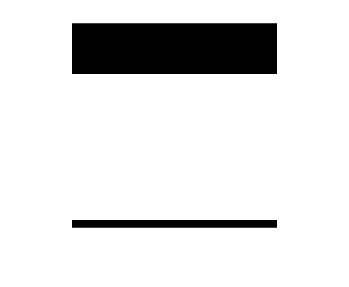

figure();
imshow(result{13});